clear all
close all

여기서는 먼저 x  에 대한 설명을 하겠습니다.

다음의 그림을 참고하겠습니다.

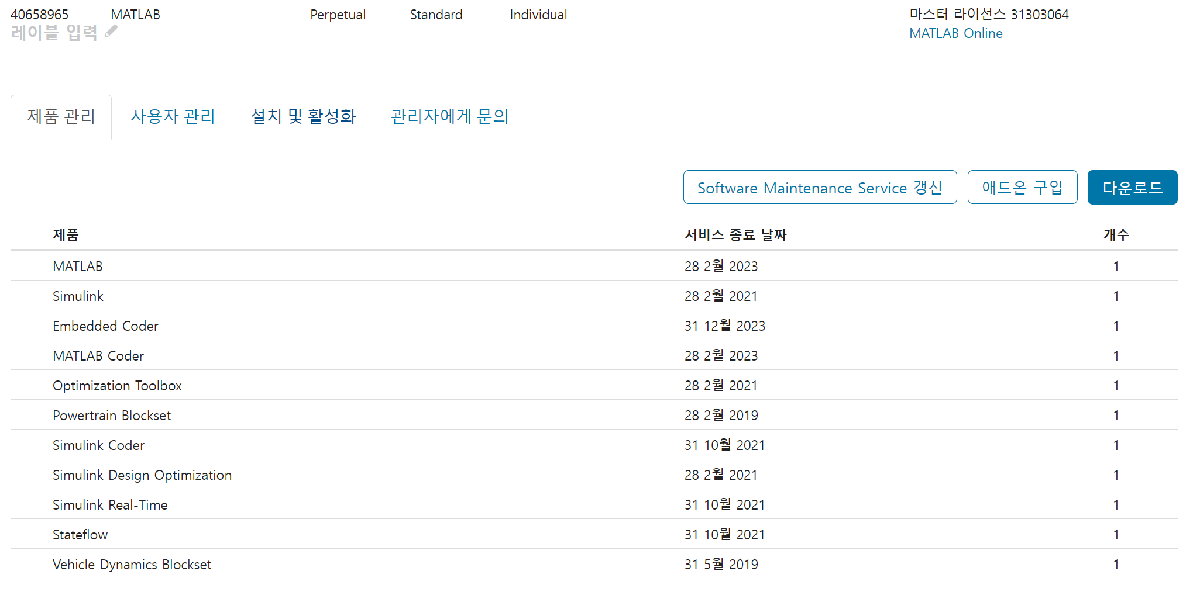


x = 1;
y = 2;

a = [1 2 3;
     3 5 7;
     7 8 9;];
 
 b = a*2;

 c = a*b;

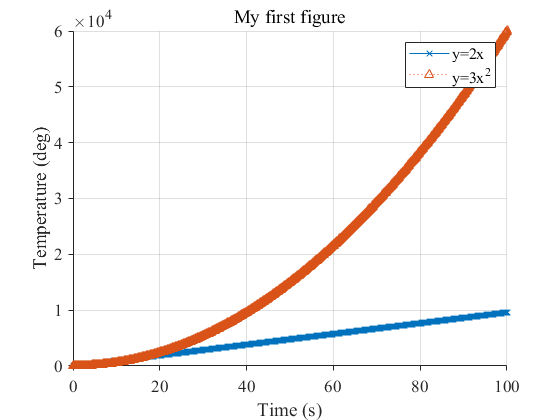

xconstant = 96;
yconstant = 6;

x = 0:0.1:100;
y = xconstant*x;
y2 = yconstant*x.^2;

figure(1)
clf
hold on
plot(x,y,'-x')
plot(x,y2,':^')
hold off
legend('y=2x','y=3x^2')
xlabel('Time (s)'); 
ylabel('Temperature (deg)')
grid on
title('My first figure')
set(gca,'FontName','Times new roman','Fontsize',13,'Tickdir','out');

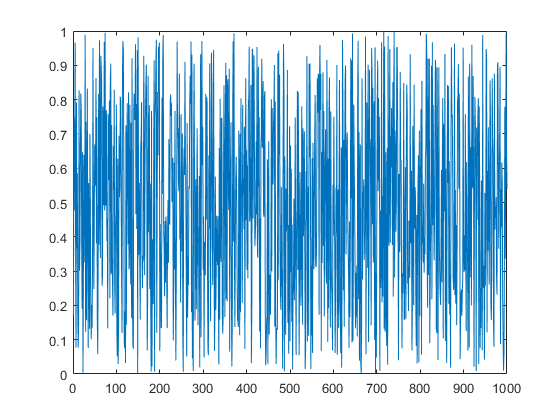

for i =1:1000
    xtime(i) = i; 
    xrand(i) = rand;
end

figure
plot(xtime,xrand)

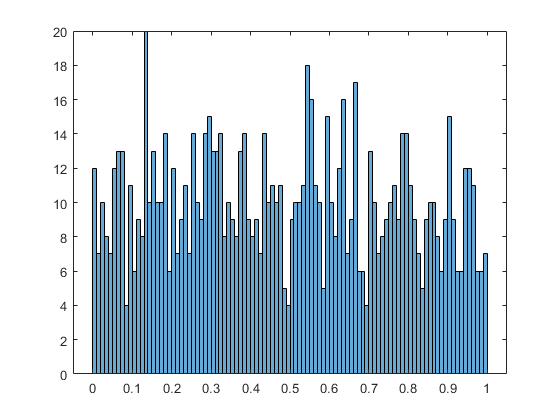


figure
histogram(xrand,100)

round = 50000

round = 20859751

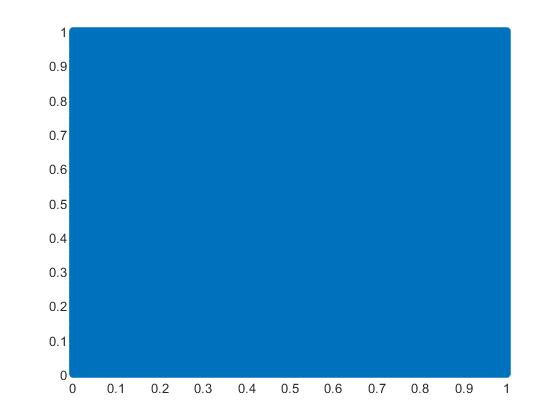

count = 0;
for i =1:round
    xdata(i) = rand;
    ydata(i) = rand;
    if (sqrt(xdata(i)^2+ydata(i)^2)<1)
        count = count + 1;
    end
end

figure
scatter(xdata,ydata)


my_pi = 4*count/round

my_pi = 3.1418

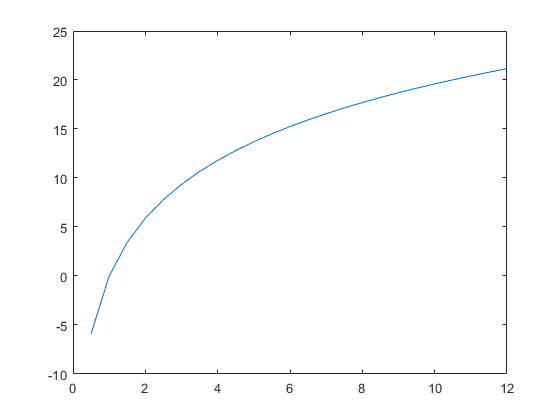

g = 9.8;%(m/s2)
pwrx = 0:0.5:12;
pwry = 2*g*log10(pwrx);
figure(3)
plot(pwrx,pwry);

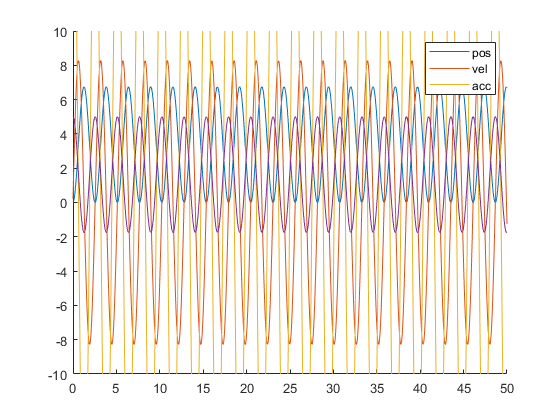


time = 0;
drone.pos = 0;
drone.despos = 5; %(m)
drone.vel =0; %(m/s)
drone.acc = 0; %(m/s2)
dt = 0.01;

result.pos = [];
result.acc = [];
result.vel = [];
result.e = [];
kp=1;
ki=0.05;
kd=0.05;
fric =0.1;

while(time<50)
   
   time = time + dt;
   
   e = drone.despos-drone.pos;
   Pval = e*kp;
   Ival = e*time*ki;
   Dval = e/dt*kd;
   PID = Pval +Ival +Dval -sign(e)*fric;
   
   drone.acc = PID-g;
   drone.vel = drone.vel + drone.acc*dt;
   drone.pos = drone.pos + drone.vel*dt;
   
   result.pos = [result.pos;drone.pos];
   result.vel = [result.vel;drone.vel];
   result.acc = [result.acc;drone.acc];
   result.e = [result.e;e];
end

figure
hold on
plot(0:dt:50,result.pos);
plot(0:dt:50,result.vel);
plot(0:dt:50,result.acc);
plot(0:dt:50,result.e);
hold off
legend('pos','vel','acc')
xlim([0 50]);ylim([-10 10])